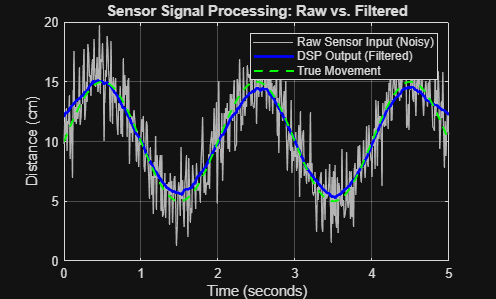

% Project: Embedded Sensor Noise Filtration Simulation
clear; clc;

% --- STEP 1: GENERATE SYNTHETIC HARDWARE DATA ---
% Simulate a system running at 100 Hz (100 samples per second)
fs = 100; 
t = 0 : 1/fs : 5; % 5 seconds of data

% True Signal: User nodding head (Sine wave)
% Amplitude = 5cm, Frequency = 0.5 Hz (Slow nod)
true_movement = 5 * sin(2*pi*0.5*t) + 10; % Centered at 10cm distance

% Noise: Electrical interference / sensor jitter
% Random static added to the signal
noise_level = 2.0; 
sensor_noise = noise_level * randn(size(t));

% The "Raw Data" your Arduino would actually see
raw_sensor_data = true_movement + sensor_noise;


% --- STEP 2: THE ALGORITHM (DSP) ---
% We use a 10-point Moving Average (Low-Pass Filter) to clean the noise
% 'movmean' is MATLAB's built-in optimized filter function
window_size = 50;
filtered_data = movmean(raw_sensor_data, window_size);


% --- STEP 3: VERIFICATION (The "Chart") ---
figure;
plot(t, raw_sensor_data, 'Color', [0.7 0.7 0.7], 'LineWidth', 0.5); % Grey = Noisy
hold on;
plot(t, filtered_data, 'b', 'LineWidth', 2); % Blue = Clean
plot(t, true_movement, 'g--', 'LineWidth', 1.5); % Green = Perfect Truth

title('Sensor Signal Processing: Raw vs. Filtered');
xlabel('Time (seconds)');
ylabel('Distance (cm)');
legend('Raw Sensor Input (Noisy)', 'DSP Output (Filtered)', 'True Movement');
grid on;


% --- STEP 4: CALCULATE ERROR (Engineering Metric) ---
% Calculate how much the noise was reduced (RMSE)
noise_error = sqrt(mean((raw_sensor_data - true_movement).^2));
filter_error = sqrt(mean((filtered_data - true_movement).^2));

fprintf('Raw Sensor Error (RMSE): %.3f cm\n', noise_error);

Raw Sensor Error (RMSE): 1.938 cm


fprintf('Filtered Output Error (RMSE): %.3f cm\n', filter_error);

Filtered Output Error (RMSE): 0.588 cm


fprintf('Improvement: %.1f%%\n', (1 - filter_error/noise_error)*100);

Improvement: 69.7%
